## Hydrological model. 

*Implement the hydrological model on the 6-year-long series of precipitation and discharge.*

clear 
close


%% Load data
load area_rating_curve.txt
load kc.txt % [-]
load P.txt % [mm/h]
load Q_obs.txt %[m^3/s]
load temperature.txt

Nyears=length(Q_obs)/(365*24);
day_month=[31 28 31 30 31 30 31 31 30 31 30 31]; %"day_month": number of days for each month
hour_month=day_month*24;
month_end=cumsum(day_month);                     %"month_end": last day of each month
month_start=month_end-day_month+1;               %"month_start": first day of each month
month_end_hour=cumsum(hour_month);                  
month_start_hour=month_end_hour-hour_month+1;

%%Parameters for the hydrological model
sw = 0.25;      %[-] Wilting point
s1 = 0.4;       %[-] Soil moisture stress threshold
n = 0.3;        %[-] Porosity
Q_b = 7;        %[m^3/s] Baseflow
t_sup = 22;     %[h] Mean superficial residence time
A = 4000;       %[km^2] Catchment area
phi = 38;       %[°] Latitude 

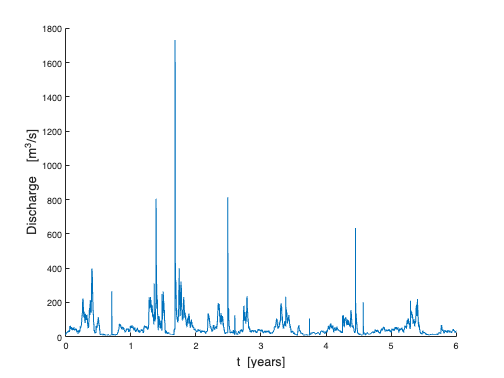

%% Plot discharge time series

figure(1)                                          %create a new figure
plot((1:length(Q_obs))/(365*24),Q_obs);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14)       %insert label y axis
box off 

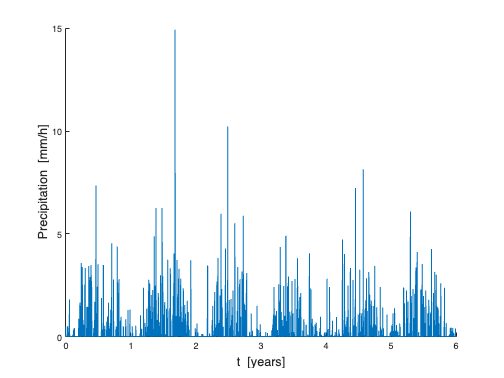

%% Plot precipitation time series

figure(2)                                          %create a new figure
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Precipitation  [mm/h]','FONTSIZE',14)   %insert label y axis
box off

### 1.Compute reference crop evapotranspiration ET0 (potential evapotranspiration) through the Thornthwaite equation 

I = sum((temperature./5).^(1.514));
a = 6.75*(10^(-7))*(I^3) - 7.71*(10^(-5))*(I^2) + 1.79*(10^(-2))*I + 0.49; %experimental exponent
D = 1:365;
delt = 0.409*sin(2*pi*D/365-1.39);
w_s = acos(-tan(phi*pi/180)*tan(delt));
N_D = 24*w_s/pi; %number of daylight hours of day D
N_M =zeros(12,1); % mean daylight hours of month m


for i=1:12
    N_M(i) = sum((N_D(month_start(i):month_end(i))))/(day_month(i)); 
end

ET_0 = ((16.*(N_M/12).*(10*temperature/I).^a)/24)./day_month'; % [mm/unit area]


### 2. Attribute arbitrary values to the parameters K_sat, c, t_sub, z.

% Hydrological model: to be calibrated

K_sat = 1e-6*(3.6e6);      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5
c = 10;              %[-] Exponent for power-law relation L(s)  1<c<20
z = 2000;              %[L] Root zone depth 1<z<2000 [mm]
t_sub = 200;          %[T] Mean sub-superficial residence time 1<t_sub<400
delta = [K_sat, c, z, t_sub];
% K_sat = 23.1423
% c = 16.4239
% z = 628.5144
% t_sub = 329.4774

### 3. Use an Euler explicit scheme to integrate the system of equations at hourly scale

% Settings
s = zeros(length(Q_obs),1);    % saturation vector
s(1) = 0.5;                    % initial arbitrary value

Vsup = zeros(length(Q_obs),1);  % superficial stored volume vector

Vsub = zeros(length(Q_obs),1); %  sub-superficial stored volume vector

N_hours_per_year = 365*24;  %number of hours per year
ET = zeros(length(Q_obs),1); 
L = zeros(length(Q_obs),1);

% Infiltration
K_sat_vect = ones(length(P),1)*K_sat;  % K_sat vector to compare with precipitation
I = min(P,K_sat_vect);

% Runoff
R = P-I;

%mode = 0 ;

%Q_mod = Q_mod_fun(P, Q_obs, ET_0, kc, delta(1),delta(2), delta(4), t_sub, delta(3), sw, s1, n, Q_obs, A, phi,mode);


for y=1:Nyears
    for m=1:12
        for h=month_start_hour(m):month_end_hour(m)
            t=(y-1)*N_hours_per_year+h; 
            if s(t)<=sw && s(t)>=0
                ET(t)= 0;
            elseif s(t)<=s1 && s(t)>sw
                ET(t)= kc(m)*ET_0(m)*((s(t)-sw)/(s1-sw));
            elseif s(t)<=1 && s(t)>s1
                ET(t)= kc(m)*ET_0(m);
            elseif s(t)>1
                    disp('Warning : s > 1')
            elseif s(t)<0
                    disp('Warning : s < 0')
            end
            L(t)=K_sat*(s(t)^c);
            s(t+1)=s(t)+((I(t)-ET(t)-L(t))*(1/(n*z)));
            Vsup(t+1)=Vsup(t)+R(t)-((t_sup^(-1))*Vsup(t));
            Vsub(t+1)=Vsub(t)+L(t)-((t_sub^(-1))*Vsub(t));
        end
    end
end


qsup=Vsup/t_sup;
qsub=Vsub/t_sub;
Qsup=A*qsup/3.6;
Qsub=A*qsub/3.6;

### 4. Test the mass balance of your system in order to ensure a correct implementation.

doTest=1;
dt=1;

%compute total discharge Q
if doTest % if doTest=1, check mass balance
    P_tot=sum(P)*dt;
    R_tot=sum(R)*dt;
    L_tot=sum(L)*dt;
    ET_tot=sum(ET)*dt;
    %"testS" balance for the root zone (input/output). testS = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testS=P_tot/(ET_tot+R_tot+L_tot+n*z*(s(end)-s(1)))

    %"testQ" balance for the whole system (input/output). testQ = 1: necessary (but not sufficient)
    %condition for the implementation to be correct
    testQ=sum(P-ET)/(sum(qsup+qsub)+n*z*(s(end)-s(1))+Vsup(end)+Vsub(end))
end

testS = 1.0000

testQ = 1.0000

### 5. Evaluate the goodness of fit of the chosen parameter set by calculating the Nash-Sutcliffe index NS.

Q_mod = Qsub+Qsup+Q_b;
Q_mod = Q_mod(1:52560,1);
NS = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS = 0.4609



Q_mod = hydrological_model(P, Q_obs, ET_0, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A, phi);
Q_mod = Q_mod(1:52560,1);
NS_old = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS_old = 0.4609

## Model calibration

Find the set of parameters {Ksat, c, tsub, z} that maximizes the Nash-Sutcliffe index. Use a simulated annealing strategy in order to find the parameter set that maximizes NS.

### 1. Define a functional form for the temperature

### 2. Attribute arbitrary values to the parameters Ksat, c, tsub, z. Run the hydrological model and evaluate NSold.

% K_sat = 1e-6*(3.6e6);      %[LT^(-1)] Hydraulic conductivity for saturated soil  10e-7<K-sat<10e-5
% c = 10;              %[-] Exponent for power-law relation L(s)  1<c<20
% z = 2000;              %[L] Root zone depth 1<z<2000 [mm]
% t_sub = 200;          %[T] Mean sub-superficial residence time 1<t_sub<400
% 
% delta = [K_sat, c, z, t_sub];

ranges = [0.99e-05*(3.6e6),19,1999,399];
upper_lim = [1e-5*(3.6e6),20,2000,400];
lower_lim = [1e-7*(3.6e6),1,1,1];
sigma = 5/100;
cr = 1/1200;

Q_mod = hydrological_model(P, Q_obs, ET_0, kc, delta(1),delta(2), delta(4), t_sup, delta(3), sw, s1, n, Q_b, A, phi);
Q_mod = Q_mod(1:52560,1);
NS_old = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))

NS_old = 0.4609

### 3. Select a new parameter set by drawing from a truncated normal distribution centered in the previous parameter set (use function TruncNormRnd.m)

delta_old=delta;
delta_new=delta;

Niter=10000;
niter = 1 ; 
while niter<Niter
    for i=1:length(delta)
        delta_new(i)=TruncNormRnd(delta_old(i),sigma,lower_lim(i),upper_lim(i));
    end
    Q_mod = hydrological_model(P, Q_obs, ET_0, kc, delta_new(1),delta_new(2), delta_new(4), t_sup, delta_new(3), sw, s1, n, Q_b, A, phi);
    Q_mod = Q_mod(1:52560,1);
    NS_new = 1- ((sum((Q_obs-Q_mod).^2))/(sum((Q_obs-mean(Q_obs)).^2)))
    
    if NS_new>NS_old
        delta_old = delta_new;
        NS_old = NS_new;

    else
        r = rand;
        if r<exp((NS_new-NS_old)/t_sa(cr,i))
            NS_old = NS_new;
        end
    end
    if NS_new >=0.85
        break
    end
    niter=niter+1;
end

NS_new = 0.4610

NS_new = 0.4605

NS_new = 0.4605

NS_new = 0.4610

NS_new = 0.4612

NS_new = 0.4612

NS_new = 0.4612

NS_new = 0.4613

NS_new = 0.4610

NS_new = 0.4613

NS_new = 0.4613

NS_new = 0.4608

NS_new = 0.4615

NS_new = 0.4615

NS_new = 0.4615

NS_new = 0.4615

NS_new = 0.4616

NS_new = 0.4615

NS_new = 0.4616

NS_new = 0.4616

NS_new = 0.4616

NS_new = 0.4617

NS_new = 0.4615

NS_new = 0.4617

NS_new = 0.4616

NS_new = 0.4616

NS_new = 0.4616

NS_new = 0.4615

NS_new = 0.4616

NS_new = 0.4617

NS_new = 0.4616

NS_new = 0.4614

NS_new = 0.4616

NS_new = 0.4617

NS_new = 0.4617

NS_new = 0.4618

NS_new = 0.4617

NS_new = 0.4619

NS_new = 0.4617

NS_new = 0.4619

NS_new = 0.4619

NS_new = 0.4620

NS_new = 0.4619

NS_new = 0.4620

NS_new = 0.4621

NS_new = 0.4621

NS_new = 0.4621

NS_new = 0.4623

NS_new = 0.4623

NS_new = 0.4622

NS_new = 0.4621

NS_new = 0.4622

NS_new = 0.4622

NS_new = 0.4622

NS_new = 0.4623

NS_new = 0.4621

NS_new = 0.4625

NS_new = 0.4625

NS_new = 0.4627

NS_new = 0.4627

NS_new = 0.4628

NS_new = 0.4630

NS_new = 0.4626

NS_new = 0.4633

NS_new = 0.4632

NS_new = 0.4630

NS_new = 0.4634

NS_new = 0.4634

NS_new = 0.4636

NS_new = 0.4635

NS_new = 0.4637

NS_new = 0.4634

NS_new = 0.4635

NS_new = 0.4636

NS_new = 0.4635

NS_new = 0.4632

NS_new = 0.4636

NS_new = 0.4632

NS_new = 0.4639

NS_new = 0.4638

NS_new = 0.4638

NS_new = 0.4640

NS_new = 0.4645

NS_new = 0.4647

NS_new = 0.4650

NS_new = 0.4649

NS_new = 0.4660

NS_new = 0.4661

NS_new = 0.4665

NS_new = 0.4655

NS_new = 0.4664

NS_new = 0.4661

NS_new = 0.4670

NS_new = 0.4665

NS_new = 0.4665

NS_new = 0.4667

NS_new = 0.4665

NS_new = 0.4667

NS_new = 0.4666

NS_new = 0.4668

NS_new = 0.4673

NS_new = 0.4672

NS_new = 0.4674

NS_new = 0.4681

NS_new = 0.4681

NS_new = 0.4676

NS_new = 0.4678

NS_new = 0.4680

NS_new = 0.4685

NS_new = 0.4681

NS_new = 0.4686

NS_new = 0.4702

NS_new = 0.4703

NS_new = 0.4709

NS_new = 0.4708

NS_new = 0.4707

NS_new = 0.4706

NS_new = 0.4715

NS_new = 0.4718

NS_new = 0.4719

NS_new = 0.4717

NS_new = 0.4718

NS_new = 0.4720

NS_new = 0.4728

NS_new = 0.4721

NS_new = 0.4726

NS_new = 0.4719

NS_new = 0.4724

NS_new = 0.4729

NS_new = 0.4735

NS_new = 0.4740

NS_new = 0.4731

NS_new = 0.4737

NS_new = 0.4738

NS_new = 0.4742

NS_new = 0.4745

NS_new = 0.4743

NS_new = 0.4764

NS_new = 0.4757

NS_new = 0.4746

NS_new = 0.4749

NS_new = 0.4754

NS_new = 0.4748

NS_new = 0.4749

NS_new = 0.4750

NS_new = 0.4770

NS_new = 0.4777

NS_new = 0.4793

NS_new = 0.4794

NS_new = 0.4803

NS_new = 0.4808

NS_new = 0.4805

NS_new = 0.4806

NS_new = 0.4796

NS_new = 0.4814

NS_new = 0.4816

NS_new = 0.4810

NS_new = 0.4812

NS_new = 0.4794

NS_new = 0.4807

NS_new = 0.4810

NS_new = 0.4810

NS_new = 0.4803

NS_new = 0.4817

NS_new = 0.4839

NS_new = 0.4838

NS_new = 0.4847

NS_new = 0.4854

NS_new = 0.4853

NS_new = 0.4838

NS_new = 0.4871

NS_new = 0.4881

NS_new = 0.4888

NS_new = 0.4885

NS_new = 0.4896

NS_new = 0.4914

NS_new = 0.4909

NS_new = 0.4909

NS_new = 0.4907

NS_new = 0.4923

NS_new = 0.4929

NS_new = 0.4927

NS_new = 0.4908

NS_new = 0.4921

NS_new = 0.4931

NS_new = 0.4908

NS_new = 0.4910

NS_new = 0.4919

NS_new = 0.4913

NS_new = 0.4914

NS_new = 0.4892

NS_new = 0.4935

NS_new = 0.4915

NS_new = 0.4938

NS_new = 0.4936

NS_new = 0.4925

NS_new = 0.4925

NS_new = 0.4935

NS_new = 0.4943

NS_new = 0.4940

NS_new = 0.4922

NS_new = 0.4933

NS_new = 0.4929

NS_new = 0.4941

NS_new = 0.4937

NS_new = 0.4953

NS_new = 0.4963

NS_new = 0.4951

NS_new = 0.4960

NS_new = 0.4971

NS_new = 0.4943

NS_new = 0.4962

NS_new = 0.4940

NS_new = 0.4939

NS_new = 0.4993

NS_new = 0.4998

NS_new = 0.4992

NS_new = 0.4968

NS_new = 0.5013

NS_new = 0.5026

NS_new = 0.5052

NS_new = 0.5042

NS_new = 0.5046

NS_new = 0.5077

NS_new = 0.5092

NS_new = 0.5102

NS_new = 0.5101

NS_new = 0.5119

NS_new = 0.5109

NS_new = 0.5101

NS_new = 0.5120

NS_new = 0.5133

NS_new = 0.5131

NS_new = 0.5120

NS_new = 0.5127

NS_new = 0.5109

NS_new = 0.5115

NS_new = 0.5151

NS_new = 0.5169

NS_new = 0.5160

NS_new = 0.5155

NS_new = 0.5152

NS_new = 0.5166

NS_new = 0.5187

NS_new = 0.5199

NS_new = 0.5220

NS_new = 0.5217

NS_new = 0.5222

NS_new = 0.5227

NS_new = 0.5217

NS_new = 0.5230

NS_new = 0.5234

NS_new = 0.5239

NS_new = 0.5266

NS_new = 0.5273

NS_new = 0.5312

NS_new = 0.5328

NS_new = 0.5311

NS_new = 0.5314

NS_new = 0.5296

NS_new = 0.5305

NS_new = 0.5346

NS_new = 0.5356

NS_new = 0.5377

NS_new = 0.5379

NS_new = 0.5380

NS_new = 0.5365

NS_new = 0.5381

NS_new = 0.5379

NS_new = 0.5394

NS_new = 0.5383

NS_new = 0.5406

NS_new = 0.5400

NS_new = 0.5413

NS_new = 0.5428

NS_new = 0.5420

NS_new = 0.5422

NS_new = 0.5419

NS_new = 0.5432

NS_new = 0.5427

NS_new = 0.5423

NS_new = 0.5437

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5453

NS_new = 0.5450

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5450

NS_new = 0.5447

NS_new = 0.5452

NS_new = 0.5453

NS_new = 0.5446

NS_new = 0.5451

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5447

NS_new = 0.5449

NS_new = 0.5442

NS_new = 0.5453

NS_new = 0.5447

NS_new = 0.5451

NS_new = 0.5446

NS_new = 0.5452

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5453

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5453

NS_new = 0.5453

NS_new = 0.5453

NS_new = 0.5447

NS_new = 0.5448

NS_new = 0.5445

NS_new = 0.5445

NS_new = 0.5441

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5444

NS_new = 0.5446

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5447

NS_new = 0.5446

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5450

NS_new = 0.5452

NS_new = 0.5448

NS_new = 0.5452

NS_new = 0.5453

NS_new = 0.5453

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5446

NS_new = 0.5446

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5446

NS_new = 0.5444

NS_new = 0.5447

NS_new = 0.5451

NS_new = 0.5441

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5446

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5444

NS_new = 0.5447

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5443

NS_new = 0.5450

NS_new = 0.5442

NS_new = 0.5448

NS_new = 0.5446

NS_new = 0.5445

NS_new = 0.5440

NS_new = 0.5424

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5451

NS_new = 0.5446

NS_new = 0.5446

NS_new = 0.5446

NS_new = 0.5451

NS_new = 0.5451

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5440

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5447

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5446

NS_new = 0.5451

NS_new = 0.5447

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5447

NS_new = 0.5452

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5446

NS_new = 0.5451

NS_new = 0.5441

NS_new = 0.5444

NS_new = 0.5448

NS_new = 0.5447

NS_new = 0.5441

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5445

NS_new = 0.5450

NS_new = 0.5445

NS_new = 0.5438

NS_new = 0.5449

NS_new = 0.5447

NS_new = 0.5448

NS_new = 0.5442

NS_new = 0.5449

NS_new = 0.5446

NS_new = 0.5449

NS_new = 0.5435

NS_new = 0.5448

NS_new = 0.5444

NS_new = 0.5449

NS_new = 0.5437

NS_new = 0.5445

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5444

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5444

NS_new = 0.5449

NS_new = 0.5444

NS_new = 0.5448

NS_new = 0.5447

NS_new = 0.5448

NS_new = 0.5448

NS_new = 0.5442

NS_new = 0.5448

NS_new = 0.5446

NS_new = 0.5447

NS_new = 0.5437

NS_new = 0.5444

NS_new = 0.5409

NS_new = 0.5448

NS_new = 0.5445

NS_new = 0.5446

NS_new = 0.5448

NS_new = 0.5446

NS_new = 0.5448

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5441

NS_new = 0.5448

NS_new = 0.5444

NS_new = 0.5447

NS_new = 0.5440

NS_new = 0.5446

NS_new = 0.5447

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5447

NS_new = 0.5448

NS_new = 0.5447

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5447

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5448

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5446

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5451

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5446

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5447

NS_new = 0.5447

NS_new = 0.5446

NS_new = 0.5444

NS_new = 0.5446

NS_new = 0.5449

NS_new = 0.5451

NS_new = 0.5447

NS_new = 0.5443

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5443

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5449

NS_new = 0.5445

NS_new = 0.5451

NS_new = 0.5451

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5446

NS_new = 0.5449

NS_new = 0.5447

NS_new = 0.5451

NS_new = 0.5444

NS_new = 0.5450

NS_new = 0.5447

NS_new = 0.5443

NS_new = 0.5450

NS_new = 0.5443

NS_new = 0.5448

NS_new = 0.5447

NS_new = 0.5448

NS_new = 0.5430

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5448

NS_new = 0.5450

NS_new = 0.5445

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5446

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5447

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5439

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5443

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5447

NS_new = 0.5448

NS_new = 0.5451

NS_new = 0.5447

NS_new = 0.5449

NS_new = 0.5443

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5448

NS_new = 0.5447

NS_new = 0.5447

NS_new = 0.5447

NS_new = 0.5449

NS_new = 0.5443

NS_new = 0.5449

NS_new = 0.5447

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5446

NS_new = 0.5445

NS_new = 0.5448

NS_new = 0.5446

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5447

NS_new = 0.5448

NS_new = 0.5449

NS_new = 0.5441

NS_new = 0.5449

NS_new = 0.5447

NS_new = 0.5447

NS_new = 0.5443

NS_new = 0.5447

NS_new = 0.5447

NS_new = 0.5445

NS_new = 0.5448

NS_new = 0.5434

NS_new = 0.5449

NS_new = 0.5446

NS_new = 0.5446

NS_new = 0.5448

NS_new = 0.5446

NS_new = 0.5447

NS_new = 0.5443

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5435

NS_new = 0.5446

NS_new = 0.5446

NS_new = 0.5434

NS_new = 0.5438

NS_new = 0.5445

NS_new = 0.5445

NS_new = 0.5437

NS_new = 0.5436

NS_new = 0.5448

NS_new = 0.5444

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5448

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5446

NS_new = 0.5447

NS_new = 0.5447

NS_new = 0.5446

NS_new = 0.5445

NS_new = 0.5442

NS_new = 0.5449

NS_new = 0.5446

NS_new = 0.5446

NS_new = 0.5448

NS_new = 0.5448

NS_new = 0.5443

NS_new = 0.5441

NS_new = 0.5446

NS_new = 0.5447

NS_new = 0.5436

NS_new = 0.5446

NS_new = 0.5445

NS_new = 0.5444

NS_new = 0.5427

NS_new = 0.5444

NS_new = 0.5448

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5451

NS_new = 0.5451

NS_new = 0.5447

NS_new = 0.5449

NS_new = 0.5446

NS_new = 0.5441

NS_new = 0.5450

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5446

NS_new = 0.5451

NS_new = 0.5445

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5451

NS_new = 0.5446

NS_new = 0.5451

NS_new = 0.5447

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5449

NS_new = 0.5451

NS_new = 0.5450

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5453

NS_new = 0.5449

NS_new = 0.5450

NS_new = 0.5453

NS_new = 0.5453

NS_new = 0.5453

NS_new = 0.5448

NS_new = 0.5452

NS_new = 0.5450

NS_new = 0.5447

NS_new = 0.5450

NS_new = 0.5447

NS_new = 0.5447

NS_new = 0.5444

NS_new = 0.5443

NS_new = 0.5446

NS_new = 0.5447

NS_new = 0.5447

NS_new = 0.5439

NS_new = 0.5447

NS_new = 0.5431

NS_new = 0.5435

NS_new = 0.5429

NS_new = 0.5422

NS_new = 0.5437

NS_new = 0.5442

NS_new = 0.5444

NS_new = 0.5429

NS_new = 0.5446

NS_new = 0.5446

NS_new = 0.5423

NS_new = 0.5446

NS_new = 0.5443

NS_new = 0.5451

NS_new = 0.5446

NS_new = 0.5453

NS_new = 0.5453

NS_new = 0.5451

NS_new = 0.5453

NS_new = 0.5454

NS_new = 0.5450

NS_new = 0.5454

NS_new = 0.5452

NS_new = 0.5448

NS_new = 0.5448

NS_new = 0.5436

NS_new = 0.5455

NS_new = 0.5454

NS_new = 0.5453

NS_new = 0.5451

NS_new = 0.5451

NS_new = 0.5447

NS_new = 0.5444

NS_new = 0.5450

NS_new = 0.5453

NS_new = 0.5455

NS_new = 0.5453

NS_new = 0.5456

NS_new = 0.5452

NS_new = 0.5455

NS_new = 0.5452

NS_new = 0.5453

NS_new = 0.5455

NS_new = 0.5454

NS_new = 0.5445

NS_new = 0.5450

NS_new = 0.5436

NS_new = 0.5447

NS_new = 0.5447

NS_new = 0.5442

NS_new = 0.5425

NS_new = 0.5441

NS_new = 0.5428

NS_new = 0.5442

NS_new = 0.5433

NS_new = 0.5431

NS_new = 0.5445

NS_new = 0.5448

NS_new = 0.5443

NS_new = 0.5444

NS_new = 0.5426

NS_new = 0.5454

NS_new = 0.5456

NS_new = 0.5457

NS_new = 0.5457

NS_new = 0.5454

NS_new = 0.5456

NS_new = 0.5457

NS_new = 0.5457

NS_new = 0.5452

NS_new = 0.5456

NS_new = 0.5451

NS_new = 0.5455

NS_new = 0.5455

NS_new = 0.5451

NS_new = 0.5455

NS_new = 0.5456

NS_new = 0.5456

NS_new = 0.5458

NS_new = 0.5453

NS_new = 0.5454

NS_new = 0.5453

NS_new = 0.5453

NS_new = 0.5455

NS_new = 0.5441

NS_new = 0.5456

NS_new = 0.5455

NS_new = 0.5456

NS_new = 0.5448

NS_new = 0.5456

NS_new = 0.5456

NS_new = 0.5456

NS_new = 0.5454

NS_new = 0.5456

NS_new = 0.5456

NS_new = 0.5452

NS_new = 0.5449

NS_new = 0.5457

NS_new = 0.5455

NS_new = 0.5453

NS_new = 0.5442

NS_new = 0.5453

NS_new = 0.5452

NS_new = 0.5455

NS_new = 0.5453

NS_new = 0.5453

NS_new = 0.5455

NS_new = 0.5451

NS_new = 0.5454

NS_new = 0.5453

NS_new = 0.5451

NS_new = 0.5446

NS_new = 0.5454

NS_new = 0.5450

NS_new = 0.5455

NS_new = 0.5443

NS_new = 0.5457

NS_new = 0.5457

NS_new = 0.5459

NS_new = 0.5459

NS_new = 0.5459

NS_new = 0.5457

NS_new = 0.5458

NS_new = 0.5459

NS_new = 0.5456

NS_new = 0.5454

NS_new = 0.5458

NS_new = 0.5456

NS_new = 0.5457

NS_new = 0.5457

NS_new = 0.5458

NS_new = 0.5458

NS_new = 0.5457

NS_new = 0.5456

NS_new = 0.5455

NS_new = 0.5456

NS_new = 0.5456

NS_new = 0.5456

NS_new = 0.5457

NS_new = 0.5458

NS_new = 0.5455

NS_new = 0.5454

NS_new = 0.5458

NS_new = 0.5458

NS_new = 0.5458

NS_new = 0.5452

NS_new = 0.5454

NS_new = 0.5454

NS_new = 0.5455

NS_new = 0.5455

NS_new = 0.5458

NS_new = 0.5458

NS_new = 0.5455

NS_new = 0.5458

NS_new = 0.5456

NS_new = 0.5457

NS_new = 0.5457

NS_new = 0.5457

NS_new = 0.5452

NS_new = 0.5456

NS_new = 0.5455

NS_new = 0.5455

NS_new = 0.5450

NS_new = 0.5452

NS_new = 0.5451

NS_new = 0.5440

NS_new = 0.5448

NS_new = 0.5447

NS_new = 0.5446

NS_new = 0.5453

NS_new = 0.5456

NS_new = 0.5446

NS_new = 0.5452

NS_new = 0.5442

NS_new = 0.5453

NS_new = 0.5449

NS_new = 0.5453

NS_new = 0.5455

NS_new = 0.5450

NS_new = 0.5456

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5454

NS_new = 0.5456

NS_new = 0.5456

NS_new = 0.5454

NS_new = 0.5455

NS_new = 0.5454

NS_new = 0.5453

NS_new = 0.5454

NS_new = 0.5452

NS_new = 0.5452

NS_new = 0.5453

NS_new = 0.5444

NS_new = 0.5454

NS_new = 0.5456

NS_new = 0.5455

NS_new = 0.5455

NS_new = 0.5449

NS_new = 0.5453

NS_new = 0.5451

NS_new = 0.5454

NS_new = 0.5453

NS_new = 0.5446

NS_new = 0.5439

NS_new = 0.5454

NS_new = 0.5452

NS_new = 0.5445

NS_new = 0.5449

NS_new = 0.5434

NS_new = 0.5454

NS_new = 0.5454

NS_new = 0.5454

NS_new = 0.5454

NS_new = 0.5455

NS_new = 0.5455

NS_new = 0.5454

NS_new = 0.5456

NS_new = 0.5453

NS_new = 0.5458

NS_new = 0.5459

NS_new = 0.5456

NS_new = 0.5455

NS_new = 0.5458

NS_new = 0.5458

NS_new = 0.5454

NS_new = 0.5458

NS_new = 0.5458

NS_new = 0.5459

NS_new = 0.5459

NS_new = 0.5456

NS_new = 0.5459

NS_new = 0.5460

NS_new = 0.5445

NS_new = 0.5458

NS_new = 0.5459

NS_new = 0.5459

NS_new = 0.5452

NS_new = 0.5457

NS_new = 0.5455

NS_new = 0.5458

NS_new = 0.5460

NS_new = 0.5454

NS_new = 0.5460

NS_new = 0.5461

NS_new = 0.5459

NS_new = 0.5458

NS_new = 0.5462

NS_new = 0.5462

NS_new = 0.5460

NS_new = 0.5461

NS_new = 0.5460

NS_new = 0.5460

NS_new = 0.5460

NS_new = 0.5460

NS_new = 0.5459

NS_new = 0.5458

NS_new = 0.5455

NS_new = 0.5460

NS_new = 0.5460

NS_new = 0.5457

NS_new = 0.5461

NS_new = 0.5462

NS_new = 0.5459

NS_new = 0.5459

NS_new = 0.5462

NS_new = 0.5462

NS_new = 0.5462

NS_new = 0.5461

NS_new = 0.5461

NS_new = 0.5456

NS_new = 0.5453

NS_new = 0.5462

NS_new = 0.5459

NS_new = 0.5459

NS_new = 0.5445

NS_new = 0.5462

NS_new = 0.5461

NS_new = 0.5462

NS_new = 0.5462

NS_new = 0.5459

NS_new = 0.5462

NS_new = 0.5461

NS_new = 0.5457

NS_new = 0.5458

NS_new = 0.5445

NS_new = 0.5448

NS_new = 0.5458

NS_new = 0.5454

NS_new = 0.5459

NS_new = 0.5451

NS_new = 0.5459

NS_new = 0.5462

NS_new = 0.5455

NS_new = 0.5460

NS_new = 0.5458

NS_new = 0.5455

NS_new = 0.5451

NS_new = 0.5457

NS_new = 0.5458

NS_new = 0.5454

NS_new = 0.5453

NS_new = 0.5461

NS_new = 0.5461

NS_new = 0.5459

NS_new = 0.5459

NS_new = 0.5453

NS_new = 0.5456

NS_new = 0.5459

NS_new = 0.5445

NS_new = 0.5427

NS_new = 0.5450

NS_new = 0.5449

NS_new = 0.5455

NS_new = 0.5455

NS_new = 0.5455

NS_new = 0.5457

NS_new = 0.5454

NS_new = 0.5440

NS_new = 0.5439

NS_new = 0.5459

NS_new = 0.5453

NS_new = 0.5458

NS_new = 0.5460

NS_new = 0.5452

NS_new = 0.5455

NS_new = 0.5448

NS_new = 0.5460

NS_new = 0.5459

NS_new = 0.5463

NS_new = 0.5462

NS_new = 0.5460

NS_new = 0.5463

NS_new = 0.5464

NS_new = 0.5453

NS_new = 0.5465

NS_new = 0.5465

NS_new = 0.5462

NS_new = 0.5463

NS_new = 0.5459

NS_new = 0.5461

NS_new = 0.5458

NS_new = 0.5459

NS_new = 0.5460

NS_new = 0.5458

NS_new = 0.5454

NS_new = 0.5455

NS_new = 0.5451

NS_new = 0.5453

NS_new = 0.5449

NS_new = 0.5449

NS_new = 0.5448

NS_new = 0.5446

NS_new = 0.5451

NS_new = 0.5455

NS_new = 0.5452

NS_new = 0.5448

NS_new = 0.5438

NS_new = 0.5452

NS_new = 0.5456

NS_new = 0.5459

NS_new = 0.5464

NS_new = 0.5464

NS_new = 0.5463

NS_new = 0.5460

NS_new = 0.5464

NS_new = 0.5464

NS_new = 0.5459

NS_new = 0.5462

NS_new = 0.5463

NS_new = 0.5462

NS_new = 0.5458

NS_new = 0.5453